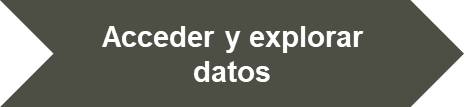

En este repositorio, hemos guardado un archivo llamadao `fisheriris_modif.csv`. Este archivo incluye datos de longitud y ancho del sépalo, y longitud y ancho del pétalo de 3 especies de iris: setosa, versicolor y virginica.

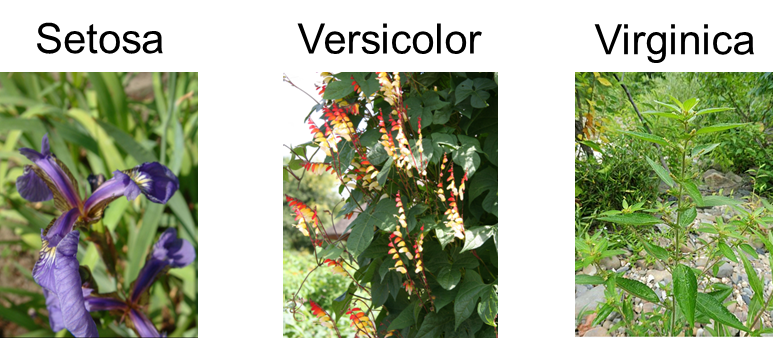

Primero  leeremos los datos en MATLAB usando el [Import Tool](https://la.mathworks.com/help/matlab/ref/importtool.html) .  Aquí seleccionaremos el archivo `fisheriris_modif.csv` y podemos pre-procesar e importar los datos.

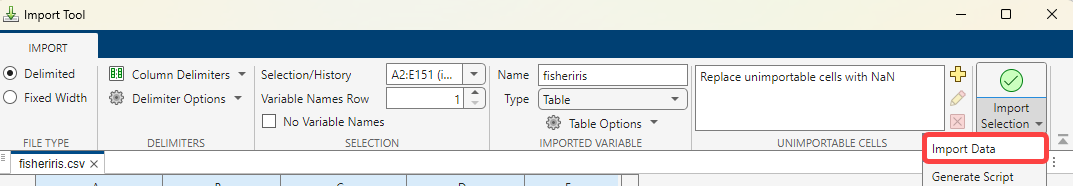

Si queremos automatizar el proceso para futuros análisis, podemos generar un script o incluso una función. 

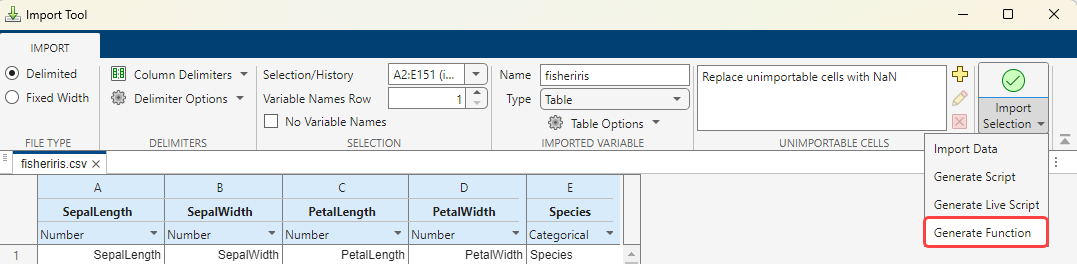

fishertable = importfile("fisheriris_modif.csv")

fishertable = 153×5 table
    SepalLength    SepalWidth    PetalLength    PetalWidth    Species
    ___________    __________    ___________    __________    _______

        5.1           3.5            1.4           0.2        setosa 
        4.9             3            1.4           0.2        setosa 
        4.7           3.2            1.3           0.2        setosa 
        4.6           3.1            1.5           0.2        setosa 
          5           3.6            1.4           0.2        setosa 
        5.4           3.9            1.7           0.4        setosa 
        4.6           3.4            1.4           0.3        setosa 
          5           3.4            1.5           0.2        setosa 
        4.4           2.9            1.4           0.2        setosa 
        4.9           3.1        

Probablemente querramos visualizar los datos para explorarlos y entenderlos. Probaremos generar las gráficas interactivamente

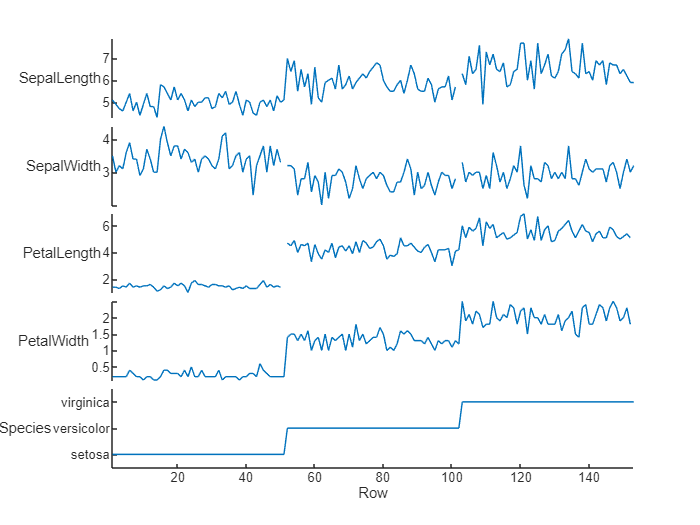

stackedplot(fishertable);

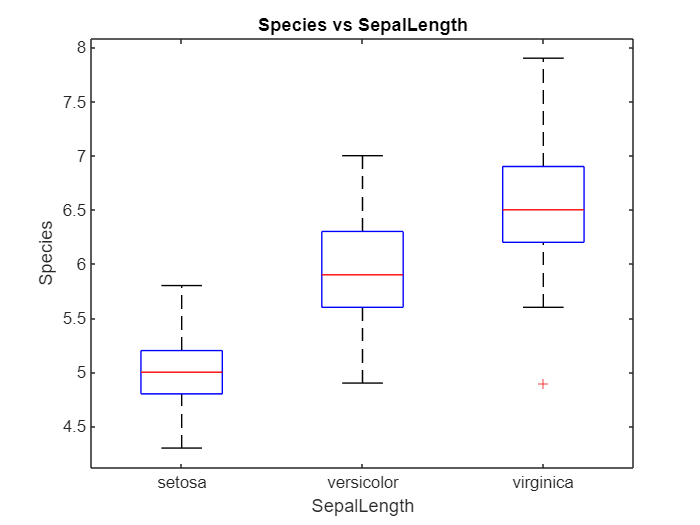

boxplot(fishertable.SepalLength,fishertable.Species);
xlabel("SepalLength");
ylabel("Species");
title("Species vs SepalLength");

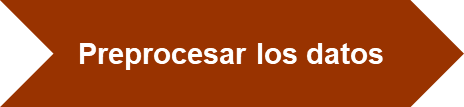

Para este ejemplo, incorporamos 3 filas con valores faltantes para mostrar cómo limpiar datos faltantes. Podemos usar una Live Task llamada [`Clear Missing Data`](https://la.mathworks.com/help/matlab/ref/cleanmissingdata.html)  para limpiar dichos valores interactivamente.

% Eliminar datos faltantes
[fishertable_clean,missingIndices] = rmmissing(fishertable);

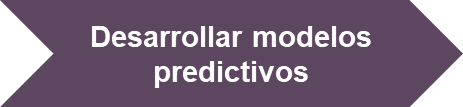

Tenemos 3 especies: setosa, versicolor y virginica. Podemos entrenar el modelo programáticamente, pero para este ejemplo vamos a utilizar una app llamada [*Classification Learner*](https://la.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html)*. *La encontrarás en la pestaña APP.

[trainedClassifier, validationAccuracy] = trainClassifier(fishertable_clean);

Ahora haremos una clasificación con los datos de 6 flores, guardados en una variable llamada `T`.

load T.mat
yfit = trainedClassifier.predictFcn(T) 

yfit = 6×1 categorical array
     versicolor 
     setosa 
     versicolor 
     virginica 
     setosa 
     setosa 


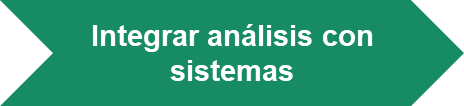

Hay diferentes maneras en que podemos integrar nuestro ánalisis en aplicaciones o sistemas complejos. Creamos esta app usando [App Designer](https://la.mathworks.com/products/matlab/app-designer.html)

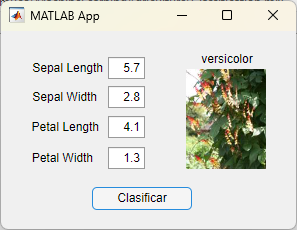

ClasificadorPlantas